# EE 451 Homework 10

#  Lisa Jacklin

#  11/25/2023

## Problem 1 

## Problem 2 

%part a: design a low pass digital filter from the butterworkth analog
%filter with the following specifications: Rp = 2dB, As = 20dB, Fs =
%1000Hz, Fp = 20Hz, and Fs = 60Hz. Use the impulse method to find the
%digital filter.

% Specifications
Rp = 2;       % Passband ripple in dB
As = 20;      % Stopband attenuation in dB
Fs = 1000;    % Sampling frequency in Hz
Fp = 20;      % Passband edge frequency in Hz
Fst = 60;     % Stopband edge frequency in Hz

% Convert frequencies to normalized values
wp = 2 * pi * Fp / Fs;
ws = 2 * pi * Fst / Fs;

% Calculate the order of the analog Butterworth filter
n = log10((10^(0.1*As) - 1) / (10^(0.1*Rp) - 1)) / (2 * log10(ws/wp));

% Round up to the nearest integer
n = ceil(n);

% Calculate the cutoff frequency for the analog Butterworth filter
wc = wp / ((10^(0.1*Rp) - 1)^(1/(2*n)));

% Design the analog Butterworth filter
[num, den] = butter(n, wc, 's');

% Convert the analog filter to a digital filter using the impulse invariant method
[num_digital, den_digital] = impinvar(num, den, Fs);

% Display the results
disp('Analog Butterworth Filter Coefficients:')

Analog Butterworth Filter Coefficients:


disp('Numerator Coefficients (analog):');

Numerator Coefficients (analog):


disp(num);

         0         0         0    0.0026



disp('Denominator Coefficients (analog):');

Denominator Coefficients (analog):


disp(den);

    1.0000    0.2748    0.0378    0.0026




disp('Digital Filter Coefficients:')

Digital Filter Coefficients:


disp('Numerator Coefficients (digital):');

Numerator Coefficients (digital):


disp(num_digital);

   1.0e-11 *

   -0.0000    0.1297    0.1297         0



disp('Denominator Coefficients (digital):');

Denominator Coefficients (digital):


disp(den_digital);

    1.0000   -2.9997    2.9995   -0.9997



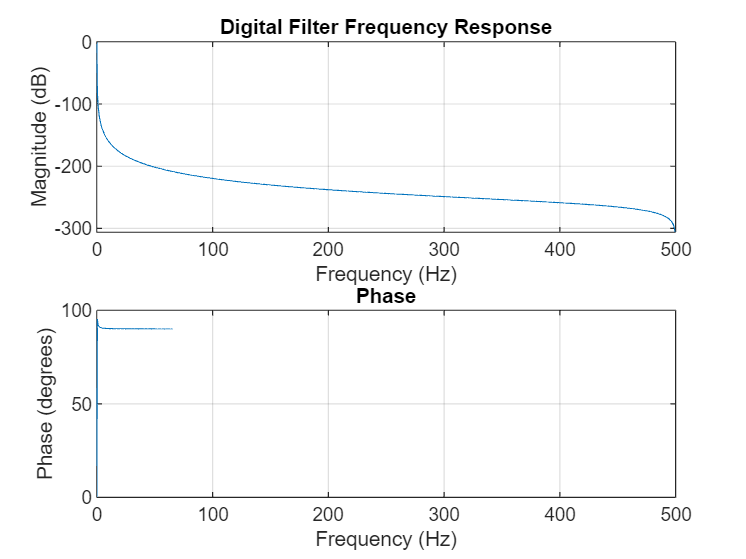


% Plot the frequency response of the digital filter
freqz(num_digital, den_digital, 1024, Fs);
title('Problem 2a: Magnitude and Phase Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;


%as can be seen by the phase response plot, the phase is linear over our
%frequency range of interest.



%Problem 2 part b: repeat the problem in [a] but now use bilinear
%transformation method to design the digital filter.
% Specifications
Rp = 2;       % Passband ripple in dB
As = 20;      % Stopband attenuation in dB
Fs = 1000;    % Sampling frequency in Hz
Fp = 20;      % Passband edge frequency in Hz
Fst = 60;     % Stopband edge frequency in Hz

% Convert frequencies to normalized values
wp = 2 * pi * Fp / Fs;
ws = 2 * pi * Fst / Fs;

% Calculate the order of the analog Butterworth filter
n = log10((10^(0.1*As) - 1) / (10^(0.1*Rp) - 1)) / (2 * log10(ws/wp));

% Round up to the nearest integer
n = ceil(n);

% Calculate the cutoff frequency for the analog Butterworth filter
wc = wp / ((10^(0.1*Rp) - 1)^(1/(2*n)));

% Design the analog Butterworth filter
[num, den] = butter(n, wc, 's');

% Convert the analog filter to a digital filter using the bilinear transformation
[num_digital, den_digital] = bilinear(num, den, Fs);

% Display the results
disp('Analog Butterworth Filter Coefficients:')

Analog Butterworth Filter Coefficients:


disp('Numerator Coefficients (analog):');

Numerator Coefficients (analog):


disp(num);

         0         0         0    0.0026



disp('Denominator Coefficients (analog):');

Denominator Coefficients (analog):


disp(den);

    1.0000    0.2748    0.0378    0.0026




disp('Digital Filter Coefficients:')

Digital Filter Coefficients:


disp('Numerator Coefficients (digital):');

Numerator Coefficients (digital):


disp(num_digital);

   1.0e-12 *

    0.3243    0.9730    0.9712    0.3249



disp('Denominator Coefficients (digital):');

Denominator Coefficients (digital):


disp(den_digital);

    1.0000   -2.9997    2.9995   -0.9997



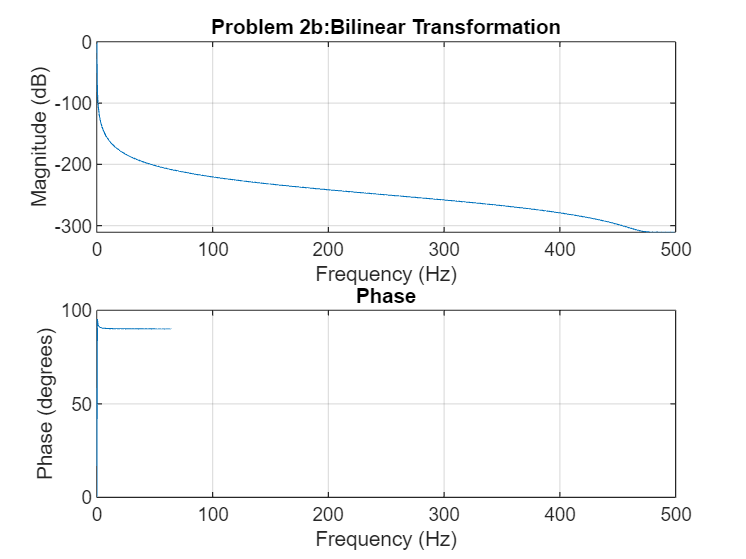


% Plot the frequency response of the digital filter
freqz(num_digital, den_digital, 1024, Fs);
title('Problem 2b:Bilinear Transformation');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

## Problem 3 

%problem 3 part a
% Specifications
Rp = 2;        % Passband ripple in dB
As = 20;       % Stopband attenuation in dB
Fs = 1000;     % Sampling frequency in Hz
Fp1 = 40;      % Lower passband edge frequency in Hz
Fp2 = 80;      % Upper passband edge frequency in Hz

% Convert frequencies to normalized values
wp1 = 2 * pi * Fp1 / Fs;
wp2 = 2 * pi * Fp2 / Fs;

% Calculate the order of the analog Butterworth filter
n = log10((10^(0.1*As) - 1) / (10^(0.1*Rp) - 1)) / (2 * log10(wp2/wp1));

% Round up to the nearest integer
n = ceil(n);

% Calculate the cutoff frequency for the analog Butterworth filter
wc = sqrt(wp1 * wp2);

% Design the analog Butterworth filter
[num, den] = butter(n, wc, 's');

% Convert the analog filter to a digital bandstop filter using the bilinear transformation
[num_digital, den_digital] = bilinear(num, den, Fs);

% Plot the magnitude and phase responses of the digital filter
figure;

% Magnitude response
subplot(2, 1, 1);
freqz(num_digital, den_digital, 1024, Fs);
title('Problem3a: Bandstop Digital Filter Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

% Phase response
subplot(2, 1, 2);
freqz(num_digital, den_digital, 1024, Fs, 'whole');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
grid on;

%is the phase linear over the frequency range of interest?


%problem 3 part b: filter the signal ekg60n data using the filters designed
%in the problem and problems 2a and 2b.



## Problem 4 

%we are given a transfer function H(s) = 100pi/(s + 100pi). wewant to
%replace the analog filter with a digital equivalent noting that the
%frequencies to the signal are less than 50Hz, with almost equal
%representation at all frequencies.

%we also are gien that there is strong interference signal at 95 Hz with
%roughly the same amplitude as those in the input signal...

%we are given the following input signal:
% xt = 5 + 5cos(40pit) + 50cos(80pit) + 5cos(190pit)
%where 0, 20, 40 Hz freuqnecy signals are the desired values and 95 hz is
%the one we wish to remove....

%part a
% Given analog filter transfer function
numerator = 100 * pi;
denominator = [1, 100 * pi];

% Given sampling frequency
fs = 200; % Hz

% Step 2: Impulse Invariant Design
[num_digital, den_digital] = impinvar(numerator, denominator, fs);

% Step 3: Normalization
[num_digital] = norm(num_digital);
[den_digital] = norm( den_digital);

% Step 4: Display filter coefficients
disp('Digital Filter Coefficients:');

Digital Filter Coefficients:


disp('Numerator Coefficients (b):');

Numerator Coefficients (b):


disp(num2str(num_digital));

1.5708


disp('Denominator Coefficients (a):');

Denominator Coefficients (a):


disp(num2str(den_digital));

1.0214



% Step 5: Magnitude and Phase Plot
w = linspace(0, pi, 1000); % Digital frequency vector
Hw = freqz(num_digital, den_digital, w, fs);

figure;
subplot(2, 1, 1);
plot(w, abs(Hw));
title('Magnitude Response');
xlabel('Digital Frequency (rad/sample)');
ylabel('|H(w)|');

subplot(2, 1, 2);
plot(w, angle(Hw));
title('Phase Response');
xlabel('Digital Frequency (rad/sample)');
ylabel('Phase(H(w))');

% Step 6: Sample the input signal
t = 0:1/fs:1; % Time vector
xt = 5 + 5*cos(40*pi*t) + 50*cos(80*pi*t) + 5*cos(190*pi*t);

% Step 7: Filter the input signal
yt = filter(num_digital, den_digital, xt);

% Step 8: Analyze the spectrum of the output signal
figure;
subplot(2, 1, 1);
pwelch(xt, [], [], [], fs, 'centered');
title('Input Signal Spectrum');

subplot(2, 1, 2);
pwelch(yt, [], [], [], fs, 'centered');
title('Output Signal Spectrum');

%how effective was this at removing the interference?

## Problem 5